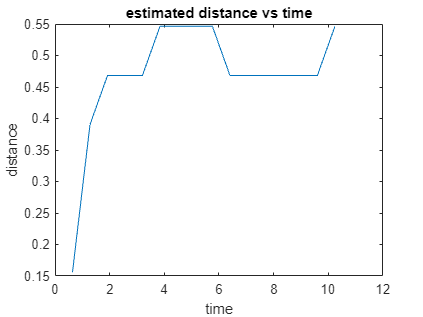

radarReference;

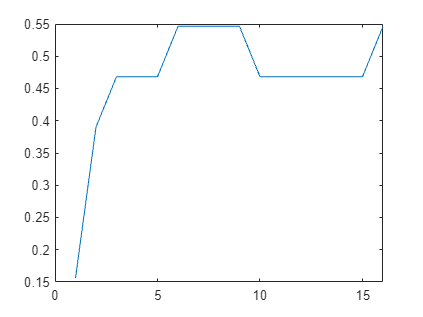


Maximum error for matlab vs simulink distance out of 16 values
 0 (absolute), 0 (percentage)


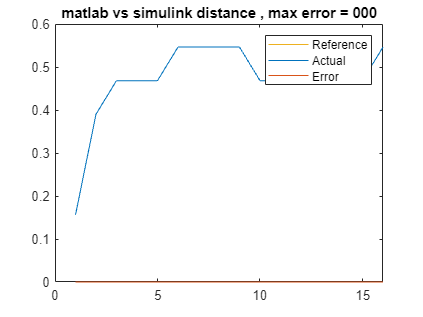

ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



simTime = length(txSig) + windowLen-nOverlap;

% Simulate model
slout = sim('radarSim1');

distSL = getLogged(slout, "dist");
distSL = distSL(windowLen-nOverlap + 1 : end); %remove dead time at start
distSL = downsample(distSL, windowLen-nOverlap);
plot(distSL);

compareData(dist, distSL, {3 1 1}, "matlab vs simulink distance");